gender = 'female';  % Or 'female' depending on the speaker
[s,fs] = audioread("s6.wav")

s =    -0.0042
   -0.0016
   -0.0031
   -0.0010
   -0.0031
   -0.0031
   -0.0031
   -0.0031
   -0.0026
   -0.0026


fs = 8000

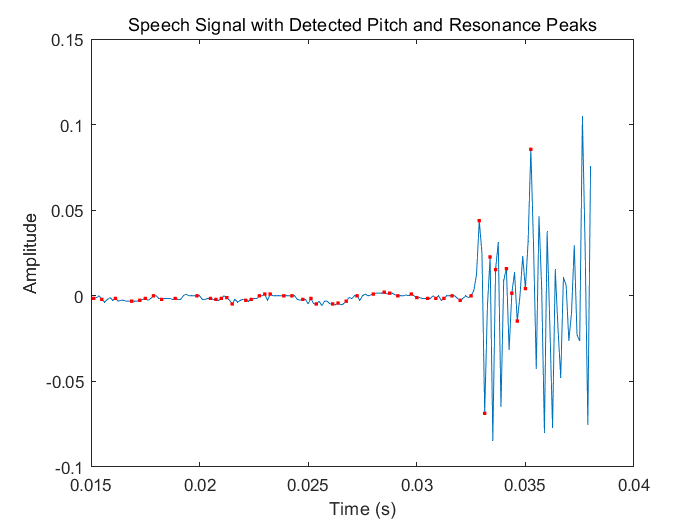

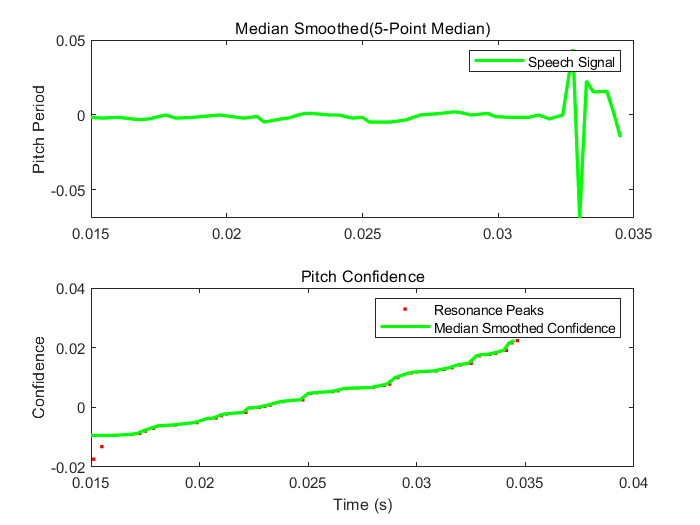

[pitch,pitch_period,peaks,med_pitch_period,med_confidence] = PitchDetector_Cepstrum(s, fs, gender);

function [pitch,pitch_period,peaks,med_pitch_period,med_confidence] = PitchDetector_Cepstrum(s, fs, gender)
N = length(s);
window = hamming(N);
s_windowed = s .* window;
s_cepstrum = real(ifft(log(abs(fft(s_windowed)))));
if strcmp(gender, 'male')
    min_pitch = 40;
    max_pitch = 167;
else
    min_pitch = 28;
    max_pitch = 67;
end

min_lag = round(fs / max_pitch);
max_lag = round(fs / min_pitch);
[~, pitch_lag] = max(s_cepstrum(min_lag:max_lag));
pitch_period = min_lag + pitch_lag - 1;
pitch = fs / pitch_period;

% Find all peaks in the cepstrum
peaks = findpeaks(s_cepstrum(min_lag:max_lag));

% Remove duplicate peak values
peaks = unique(peaks);

% Convert peak values to lag values
peak_lags = min_lag + find(ismember(s_cepstrum(min_lag:max_lag), peaks)) - 1;

% Convert lag values to pitch periods
peak_periods = peak_lags - 1;

% Convert pitch periods to times
peak_times = peak_periods / fs;

% Calculate median smoothed pitch period and confidence
med_pitch_period = medfilt1(peak_periods, 5);
med_confidence = medfilt1(peaks, 5);

% Plot the speech signal
t = (0:length(s)-1) / fs;
idx = find(t >= 0.015 & t <= 0.038);
figure;
plot(t(idx), s(idx));
xlabel('Time (s)');
ylabel('Amplitude');
title('Speech Signal with Detected Pitch and Resonance Peaks');

hold on;

% Plot the resonance peaks as points
plot(peak_times, s(peak_periods+1), 'r.');
hold off;

end